% data = readtable("scan_1632596590.csv");
% data = readtable("scan_1632600507.csv");  % A scan with funky values
% data = readtable("scan_1632782303.csv");    % rectangle
% data = readtable("scan_1632782697.csv");
% data = readtable('scan_1632838405.csv');    % 9/28 scan, low density
data = readtable('scan_1632838953.csv');    % full scan

xPos = deg2rad(data.xPos);
yPos = deg2rad(data.yPos + 90);
distance = data.distance;

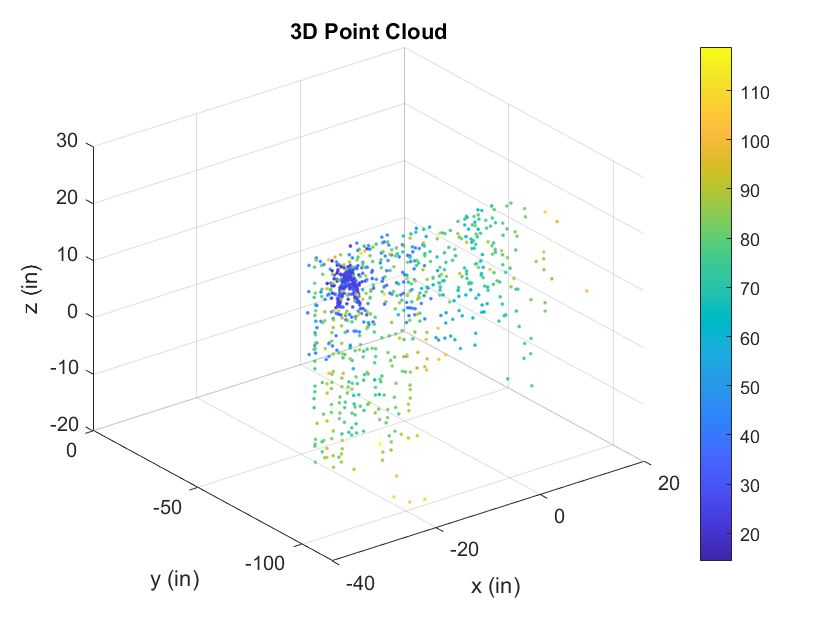

[x, y, z] = sph2cart(xPos, yPos, distance);
% make a mesh
scatter3(x, y, z, 20, distance, ".");
xlabel("x (in)"); ylabel("y (in)"); zlabel("z (in)");
colorbar(); title("3D Point Cloud");

mask1 = (abs(distance) < 60);
xPos_filtered = xPos(mask1);
yPos_filtered = yPos(mask1);
distance_filtered = distance(mask1);

[x, y, z] = sph2cart(xPos_filtered, yPos_filtered, distance_filtered);

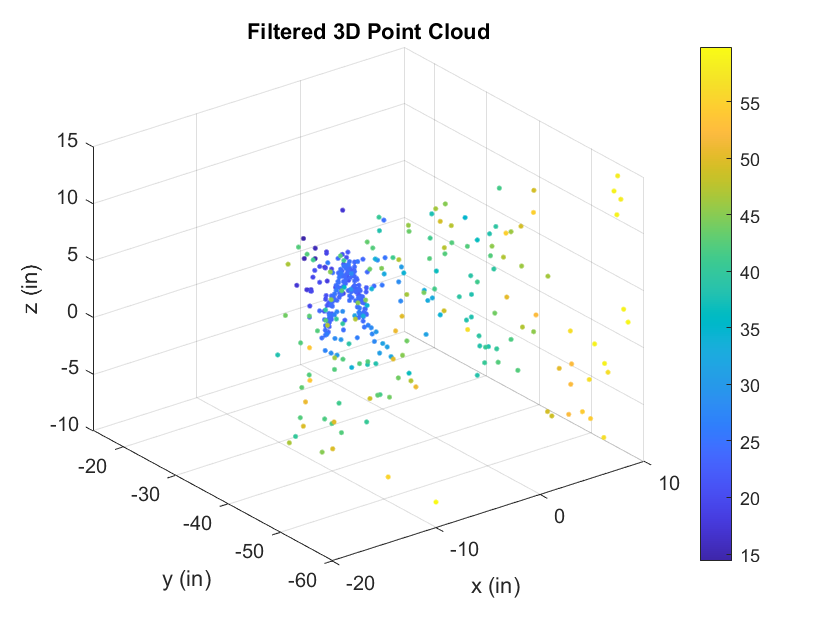

scatter3(x, y, z, 50, distance_filtered, ".")
xlabel("x (in)"); ylabel("y (in)"); zlabel("z (in)");
colorbar(); title("Filtered 3D Point Cloud")

% scatter(x(mask), y(mask), 10, distance_filtered(mask), '.')
% colorbar()

% mask1 = (abs(distance) < 35);
% % mask1 = (y > -25);
% 
% [xPos_sph, yPos_sph, dist_sph] = cart2sph(x(mask1), y(mask1), z(mask1));
% xPos_sph = rad2deg(xPos_sph) + 180;
% max(xPos_sph)
% min(xPos_sph)
% yPos_sph = rad2deg(yPos_sph) + 180;
% max(yPos_sph)
% min(yPos_sph)